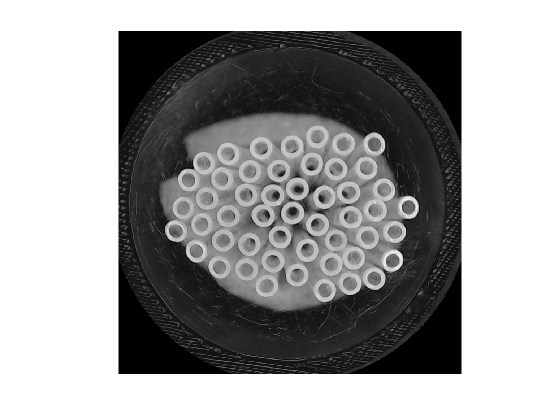

clear all; close all;

img = imread('needles_50.png');
img = rgb2gray(img);
imshow(img);

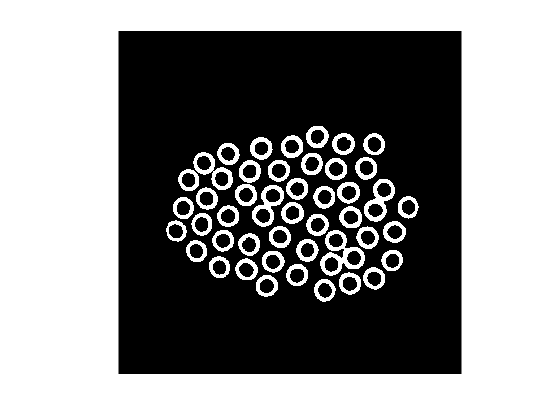


%--------------------
imgBina = img > 167;
imgBina = medfilt2(imgBina, [7,7]);

imshow(imgBina);

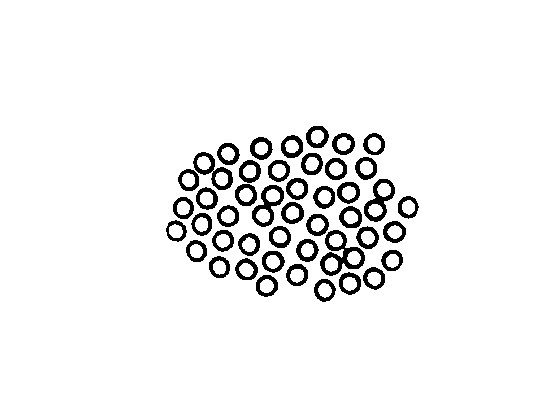


invert = 1- imgBina;
imshow(invert);


[L,count] = bwlabel(invert);
n = count-1;